# Test Gradient Ascent

*ZDR, 2021-04-09*

## Setup

% Vectorized function for surface plot
fun_vectorized = @(R) R(:, 1) .* R(:, 2) - R(:, 1).^2 - R(:, 2).^2 - 2 * R(:, 1) - 2 * R(:, 2) + 4;
% Gradient function for gradient ascent
grad = @(r) [...
    -2 - 2 * r(1) + r(2), ...
    -2 + r(1) - 2 * r(2) ...
];

### Visualize function

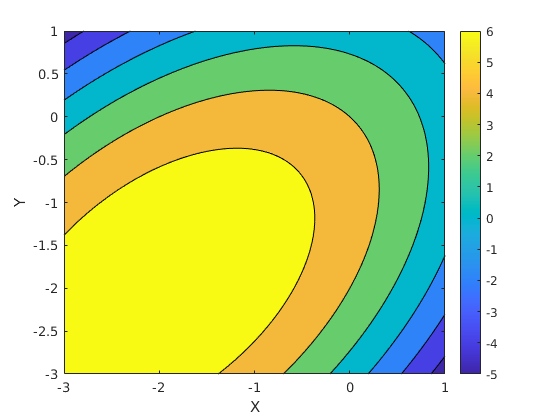

% Generate data
[X, Y] = meshgrid(linspace(-3, +1), linspace(-3, +1));
F_v = fun_vectorized([reshape(X, [], 1), reshape(Y, [], 1)]);
F = reshape(F_v, size(X));
% Plot surface
clf;
contourf(X, Y, F)
xlabel("X")
ylabel("Y")
colorbar

## Test Gradient Ascent

Example of a case where gradient ascent will converge.

%% Run gradient ascent
r_0 = [0.7, 0.5];
delta = 0.9;
lambda_0 = 0.9;
tolerance = 1e-3;
n_max = 100;

% Run the algorithm
R = gradient_ascent(grad, r_0, delta, lambda_0, tolerance, n_max);
% Print some diagnostic information
fprintf('Final iteration location: %4.3e, %4.3e', R(end, 1), R(end, 2));

Final iteration location: -2.000e+00, -2.000e+00

fprintf('Iterations to termination: %d / %d', size(R, 1) - 1, n_max);

Iterations to termination: 10 / 100

fprintf('Norm of gradient at termination: %4.3f', norm(grad(R(end, :))));

Norm of gradient at termination: 0.001

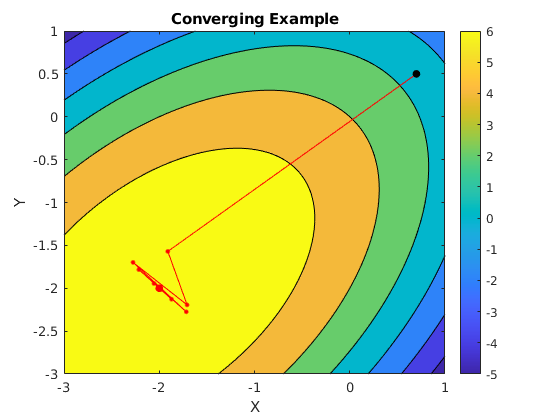


% Visualize convergence history
clf;
contourf(X, Y, F); hold on;
plot(R(:, 1), R(:, 2), "r")
plot(R(:, 1), R(:, 2), "r.", "MarkerSize", 10)
plot(R(1, 1), R(1, 2), "k.", "MarkerSize", 20)
plot(R(end, 1), R(end, 2), "r.", "MarkerSize", 20)
title('Converging Example')
xlabel("X")
ylabel("Y")
colorbar

## Test with other parameters

Example where gradient ascent will not converge.

%% Run gradient ascent
r_0 = [0.7, 0.5];
delta = 1.1; % delta > 1 causes stepsize to grow; this prevents convergence
lambda_0 = 0.9;
tolerance = 1e-3;
n_max = 100;

% Run the algorithm
R = gradient_ascent(grad, r_0, delta, lambda_0, tolerance, n_max);
% Print some diagnostic information
fprintf('Final iteration location: %4.3e, %4.3e', R(end, 1), R(end, 2));

Final iteration location: 1.125e+245, -1.125e+245

fprintf('Iterations to termination: %d / %d', size(R, 1) - 1, n_max);

Iterations to termination: 100 / 100

fprintf('Norm of gradient at termination: %4.3e', norm(grad(R(end, :))));

Norm of gradient at termination: 4.772e+245

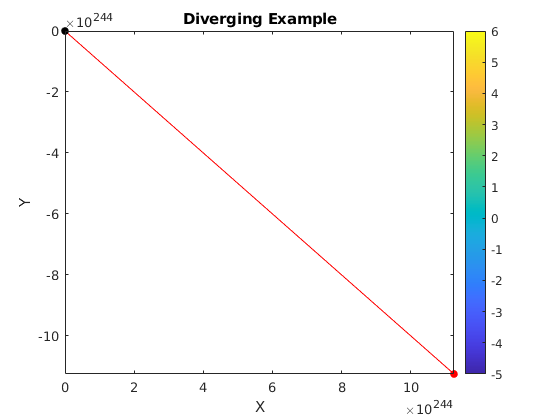


% Visualize convergence history
clf;
contourf(X, Y, F); hold on;
plot(R(:, 1), R(:, 2), "r")
plot(R(:, 1), R(:, 2), "r.", "MarkerSize", 10)
plot(R(1, 1), R(1, 2), "k.", "MarkerSize", 20)
plot(R(end, 1), R(end, 2), "r.", "MarkerSize", 20)
title('Diverging Example')
xlabel("X")
ylabel("Y")
colorbar